Данные варианта

A = [-6, 19, -13, 10;
    0, -9, 6, 0;
    0, -15, 9, 0;
    -4, 8, -7, 6];
B = [-2, 0;
    2, 0;
    4, 0;
    0, 0];
C = eye(4);
% 
% x0 = [1; 1; 1; 1];


Нахождение собственных чисел матрицы А

eA = eig(A)

eA =   -0.0000 + 2.0000i
  -0.0000 - 2.0000i
  -0.0000 + 3.0000i
  -0.0000 - 3.0000i


Проверка управляемости собственных чисел

Создание матрицы управляемости

U = ctrb(A, B);
rankU = rank(U);

Ранговый критерий

I = eye(4);
rank([A - (1+1i)*I, B]);
rank([A - (1-1i)*I, B]);
rank([A - (-1)*I, B]);
rank([A - (1)*I, B]);

Матрица гамма и матрица Y

% G1=[-2, 0, 0 ,0;
%     0, -3, 0, 0;
%     0, 0, -6, 0;
%     0, 0, 0, -8];
% G1=[-2, 0, 0 ,0;
%     0, -20, 0, 0;
%     0, 0, -200, 1;
%     0, 0, 0, -200];
% G1=[-2, 0, 0 ,0;
%     0, -20, 0, 0;
%     0, 0, 0, 3;
%     0, 0, -3, 0];
G1=[-3, 0, 0 ,0;
    0, -2, 0, 0;
    0, 0, -4, 10;
    0, 0, -10, -4];
G = -G1;
Y = [1, 1, 1, 1;
    1, 1, 1, 1];

Решение уравнения сельвестра

BY = B*Y;
P1 = sylvester(A, G, BY);

Вычисление матрицы регулятора

P = fillmissing(P1, "constant", 0);
K = -Y*pinv(P)

K =   -54.4000  124.3000  -92.6000  112.0000
  -54.4000  124.3000  -92.6000  112.0000


Матрица для модели

M = A+B*K;
eM = eig(M)

eM =   -4.0000 +10.0000i
  -4.0000 -10.0000i
  -3.0000 + 0.0000i
  -2.0000 + 0.0000i


Построение графиков

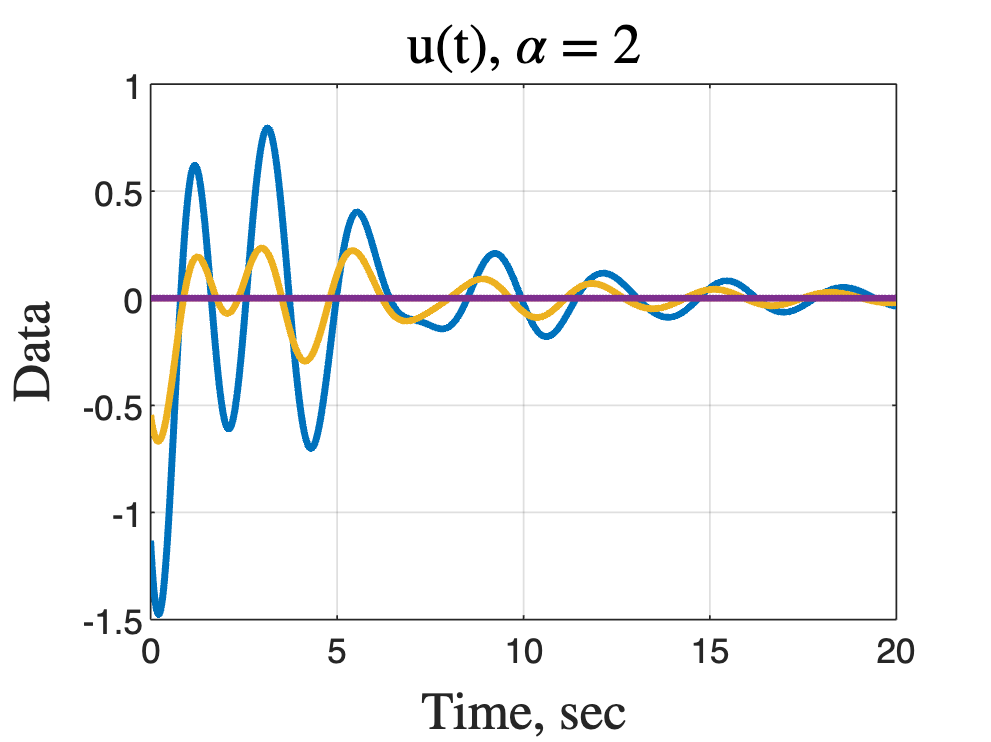

plot(out.u, 'LineWidth', 2);
title('u(t), $\alpha$ = 2','Interpreter', 'latex', 'FontSize', 16);
ylabel('Data', 'Interpreter', 'latex', 'FontSize', 15);
xlabel('Time, sec', 'Interpreter', 'latex', 'FontSize', 15);
grid on;
hold off;

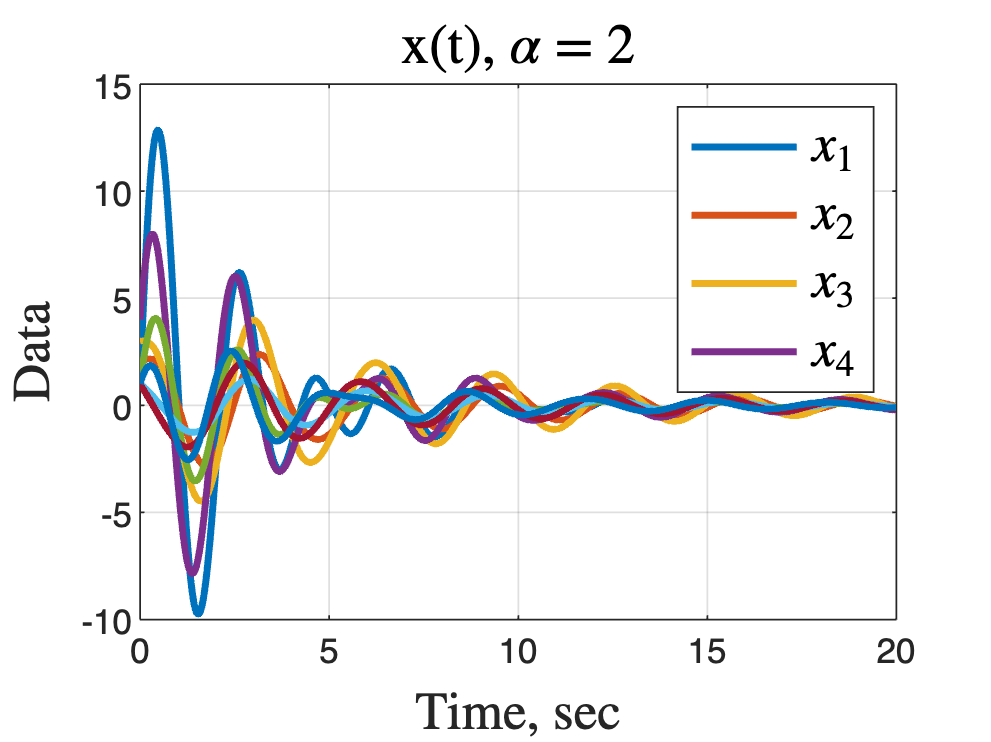


plot(out.x, 'LineWidth', 2);
grid on;
title('x(t), $\alpha$ = 2','Interpreter', 'latex', 'FontSize', 16);
ylabel('Data', 'Interpreter', 'latex', 'FontSize', 15);
xlabel('Time, sec', 'Interpreter', 'latex', 'FontSize', 15);
legend("$x_{1}$","$x_{2}$","$x_{3}$", "$x_{4}$", 'Interpreter', 'latex', 'FontSize', 15);
hold off;